%exam 11 jan 2019

EX1

B_1

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a4 positive real
syms d1 positive real

alpha = [pi/2, pi/2, pi/2, 0];
a=[0,0,0,a4];
d=[d1,0,q3,0];
theta=[q1,q2,pi,q4];

table=[alpha',a',d',theta'];

[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
A2_3=A{3};
A3_4=A{4};

A0_1

$$A0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3

$$A2\_3 = \left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 1 & 0 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & a_{4}\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & a_{4}\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

B_2

O4_h = [0 0 0 1]';
p4_h = T*O4_h %he said that this is not efficient

$$p4\_h = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 1 \end{array}\right)$$

C_1

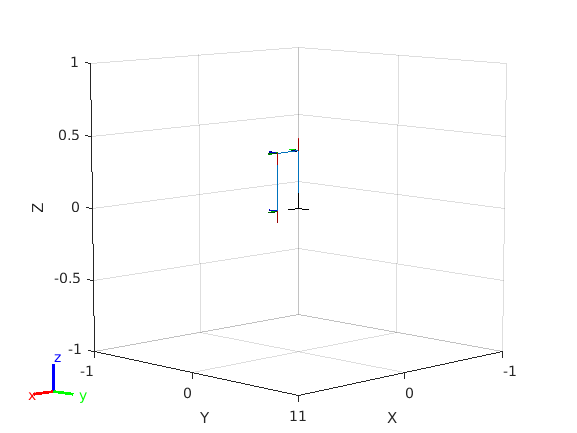

%useless unsignment, they are ignored 
q1=pi;
q2=pi;
q3=pi;
q4=pi;

%must be small value to show the robot in a good way
a4=0.4;
d1=0.4;

alpha_no_sym = [pi/2, pi/2, pi/2, 0];
a_no_sym=[0,0,0,a4];
d_no_sym=[d1,0,q3,0];
theta_no_sym=[q1,q2,pi,q4];

%Note: it has different format respect to Sveva's DHMatrix function
DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym'];
joints = 'RRPR';
robot_model = build_robot_model(joints, DHTable);

%set to position using build_configuration
q1 = 0;
q2 = pi/2;
q3 = 0.2;   % L
q4 = 0;
array_joint_values = [q1,q2,q3,q4];
config = build_configuration(robot_model, array_joint_values);
show(robot_model, config);

%show(robot_model, randomConfiguration(robot_model));

C_2

q1=0;
q2=pi/2;
L = sym('L');
q4=0;
q3 = L;

a4=sym('a4');
d1=sym('d1');

subs(p4_h)

$$ans = \left(\begin{array}{c} L\\ 0\\ d_{1}-a_{4}\\ 1 \end{array}\right)$$

EX 2

A

f_r = get_f_r(T)
% alternative way to get p4
q1=0;
q2=pi/2;
syms L real;
q4=0;
q3 = L;

subs(f_r(1:3))

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a4 real
syms d1 real

%manual calculus of JL
JL = simplify(jacobian(f_r(1:3),[q1 q2 q3 q4]))
%calculus of both part of jacobian matrix
[Jl, Ja] = geometric_jacobian(f_r, joints, [q1 q2 q3 q4], table)
rank(Ja)

B_1

%Jacobian in configuration config_0 = (0 pi/2 L 0)'
q1 = 0;
q2=pi/2;
syms L real;
q3 = L;
q4=0;

Jac = [Jl;Ja];
Jac_0 = subs(Jac);
J0_l = subs(Jl)
J0_a = subs(Ja)

Since:    v = JL(q) q' and w = JA(q) q'

The joints velocities q'_a that produces zero velocity at the task level belongs to null space of JL

vel_q_a = null(J0_l)

%check if also w is equal to zero with q'_a (vel_q_a)
w_a = J0_a*vel_q_a

So, there are no joint velocities that generates also zero angular veclocity w

B_2

A velocities = (v w) is feasible if it belongs to range space of J

range_space = orth(Jac_0)
v = [1 0 1 0 0 -2]'
vel_q_b = linsolve(range_space, v)

So, v velocity is not feasible

B_3

NullSpaceJ=null(Jac_0') 